# Project : Ising model

## Econophysics : Financial modelling with natural Science

*Par Sidney Verée, Adam GUEMOUNE ,Bolarinwa SOUHOUIN, Yannick Ivan Hyacime TAPSOBA*

Ce notebook ne sert que de support technique ainsi que d'outil de visualisation du rapport.

Dans un premier temps on initialise notre matrice aleatoirement  (S) et on l'etand (SL) de telle sorte a faciliter l'acces des voisin de tous les agent .

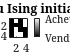

clear;

n = 4;


%Initialisation
rng(123456);

S = zeros(n,n);
for i = 1:n
    for j = 1:n
        if rand < 0.5
            S(i,j) = -1;
        else
            S(i,j) = 1;
        end
    end
end

%SL
SL = zeros(n+2,n+2);
% Copier S au centre de SL
for i = 2:n+1
    for j = 2:n+1
        SL(i,j) = S(i-1,j-1);
    end
end

%BORD
for i = 2:n+1
    SL(i,1) = SL(i,n+1);     
    SL(i,n+2) = SL(i,2);     
    SL(1,i) = SL(n+1,i);     
    SL(n+2,i) = SL(2,i);     
end

SL(1,1) = SL(n+1,n+1);
SL(1,n+2) = SL(n+1,2);
SL(n+2,1) = SL(2,n+1);
SL(n+2,n+2) = SL(2,2);

% Affichage du réseau initial S
figure;
imagesc(S);
colormap(gray);
colorbar('Ticks', [-1, 1], 'TickLabels', {'Vendre', 'Acheter'});
title('Réseau Ising initial');
axis square;

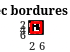


% Affichage de SL 
figure;
imagesc(SL);
colormap(gray);
title('Réseau Ising avec bordures périodiques (SL)');
axis square;
hold on;

% Ajout bordure rouge 
x_border = [1.5, n+1.5, n+1.5, 1.5, 1.5];
y_border = [1.5, 1.5, n+1.5, n+1.5, 1.5];

% Tracee bordure rouge
plot(x_border, y_border, 'r-', 'LineWidth', 2);

hold off;

Calcule de la magnetisation (**sentiment global du marché** / **Moyenne du marché **)

function magn= magn_mean(System,n)
    %Nombre de spin dans S
    squared_sum = n*n;

    %Valeur total des spin 
    SUM = sum(System(:));
    
    %Donc on a une moyenne de leur valeur 
    magn = 1/(squared_sum) * SUM;
end

fprintf("%d ≈ %.2f \n",magn_mean(S,n), magn_mean(S,n));



-2.500000e-01 ≈ -0.25 


### Resentie de l'agent ( i , j ) ou Hamiltonien local  pour **Glauber** :


$$h^{(k)}_{i, j}(t) = - \sum_{i', j'} S^{(k)}_{i', j'}(t) + \alpha S^{(k)}_{i, j}(t) |M^{(k)}(t)| - \sum_{k_1 \ne k} \gamma M^{(k_1)}(t)
$$


on le deconpose en 3 terme : 

$- \sum_{i', j'} S^{(k)}_{i', j'}(t) $ qui represent l'envie du trader de se differencier des voisin 

$+ \alpha S^{(k)}_{i, j}(t) |M^{(k)}(t)|$ le besoin de gregation du trader par raport au marchee complet  ( avec un coeficiant $\alpha $ = 20 ??? )

$- \sum_{k_1 \ne k} \gamma M^{(k_1)}(t)$ represente la force des autre actif coreel a celui qu'on etudiee K.

# INCOHERENCE DANS LES RESULTAT A REFAIRE !

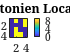

function H = H_loc(i , j, k , S , K_all, alpha, )
    n = size(S,1);
    voisin = %???;
    Moy_marche_ij = abs(magn_mean(S, n));
    Autre_action = 0;


    if k == 1
        Autr_act = 0;

    elseif k > 1 
        Autr_act = 
    
    end 
    H = -voisin + (alpha * S(i,j) * Moy_marche_ij) - (gamma* Autre_action);
end


H_loc

figure;
imagesc(H_local);
colorbar;
title('Hamiltonien Local');
axis square;


#### Prise de decision ou Iteration du model d'Ising avec algo Gobolt :

Si \beta soit le parametre de temperature (l'inverse de la temperature ) 

Augmente on a moins de prise de desision car p tendra vers 0.

Diminue on a plus de desision aleatoire 